clear;
close all;
clc;

## Load the raw data

load('bp.mat');

## Plot the raw time signal

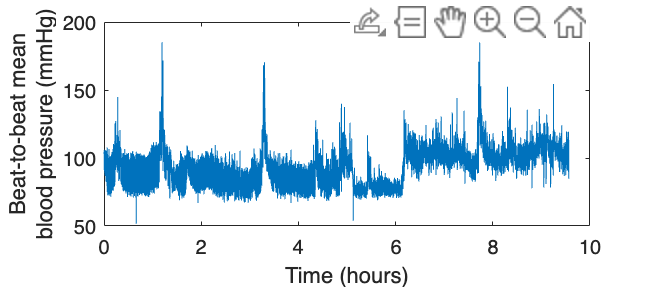

fs = 20;
t = (0:length(bp)-1)'/fs;
figure('Units','centimeters','Position',[0,0,25,11],'Color','w');
plot(t/3600, bp);
xlabel('Time (hours)');
ylabel({'Beat-to-beat mean','blood pressure (mmHg)'});

## Baseline attenuation: Highpass filter on the BP signal

The lower limit of the LF range is 0.04 Hz. With a cut-off frequency at 0.01 Hz, one can check (with the freqz function for instance) that we do not attenuate significantly any frequency component >= 0.04 Hz. Therefore, 0.01 Hz is a good trade-off between effective baseline cancellation and preservation of the frequency bands of interest.

[b,a] = butter(2, 0.01/(fs/2), 'high');
bp = filtfilt(b, a, bp);

## Spectrogram of the BP signal

Adjust the window duration below to a better value and explain your choice.

winduration = 2/0.04;    % Window duration in seconds: Find a better suited value
window = round(winduration*fs);
noverlap = round(0.95*winduration*fs);  % Overlap of 95%

figure('Units','centimeters','Position',[0,0,30,11],'Color','w');
spectrogram(bp, window, noverlap, [], fs, 'yaxis');
ylim([0,0.4]);
colormap('jet');
title('Spectrogram of the beat-to-beat mean BP signal');

% Adjust the lower limit of the colormap to a better value to improve the
% readability of the spectrogram.
cmaplowlim = -40%min(get(gca, 'clim')); % Lower colormap limit: Find a better value

cmaplowlim = -40

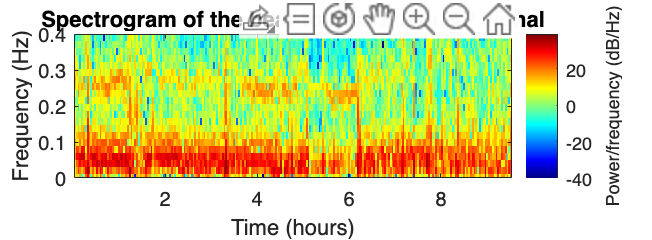

set(gca, 'clim', [cmaplowlim, max(get(gca, 'clim'))]);

### Question 1

We need a window length of at least 1/0.04 Hz = 20 s. We took the double to have some margin. However, taking a larger than necessary window length would increase the frequency resolution but decrease the time resolution.

### Question 2

We notice visually that there are no values below -40 dB/Hz. Therefore, we set the minimum value of the axis to -40 dB/Hz.

### Question 3

When looking at these 3 timepoints, we notice that:

at T = 2 h, the sympathetic activity is much stronger than the vagal activity,

at T = 4 h, the two bands are roughly the same, 

and at T = 6 h, the vagal activity is slighty more intense than the sympathetic activity. 

Hence the sympathovagal balance moves toward a stronger sympathetic activity over the three timepoints.

### Question 4

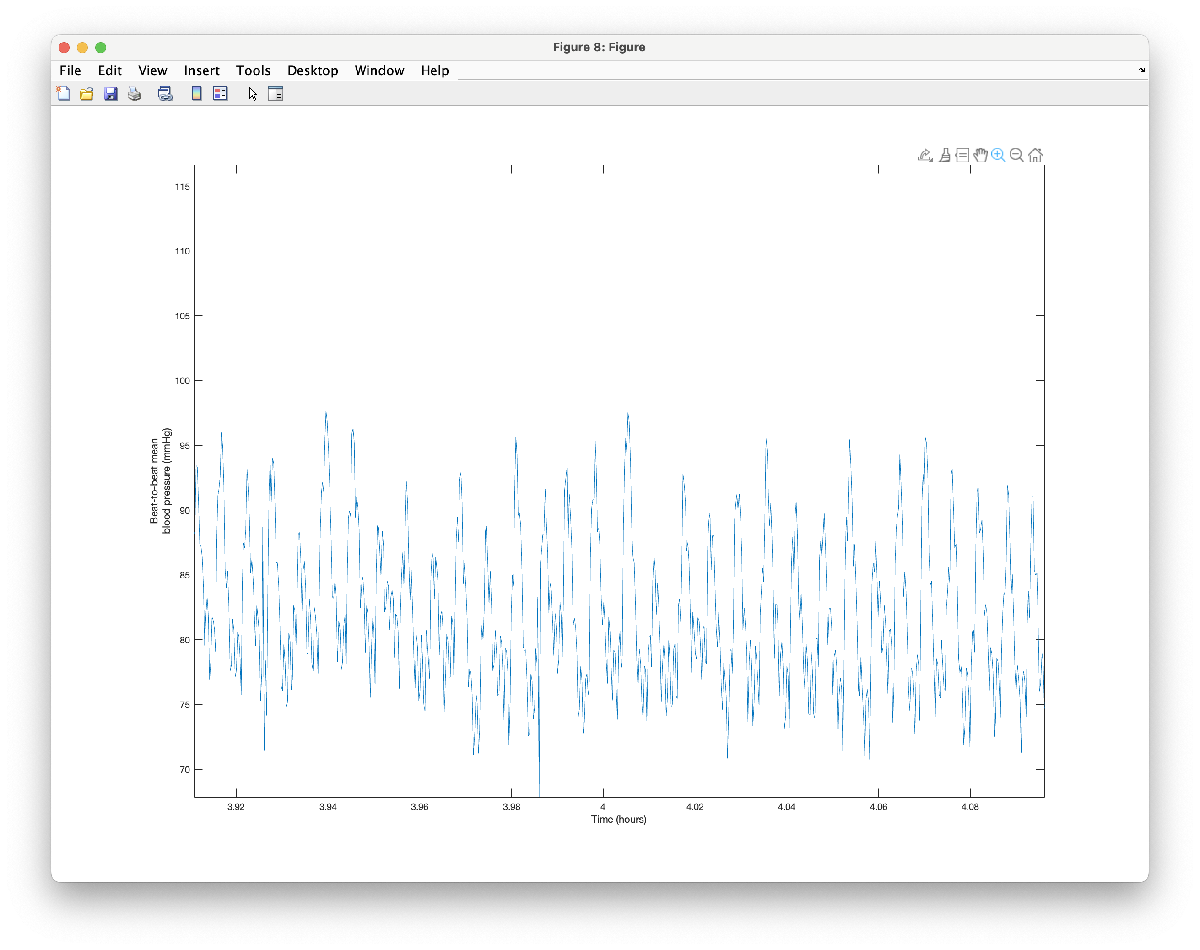

## Exercise: Respiration signal of a patient suffering from sleep apnea

### Question 1

The window length must be at least 1/(8/60) s = 7.5 s to capture the frequency of the normal respiratory activity, but shorter than 20 seconds to capture the occasional periods of apnea.